Lets begin with the linear model, first just looking at some trajectories.

figure(1)
clf
hold on
xlim([0 250])
xlabel('Time')
ylabel('Number of Stem Cells')

figure(2)
clf
hold on
xlim([0 250])
xlabel('Time')
ylabel('Number of TA Cells')

figure(3)
clf
hold on
xlim([0 250])
xlabel('Time')
ylabel('Number of FD Cells')

for i = 1:25
    [N0,N1,N2,times] = sim(18,0,0,250,"lin");
    figure(1)
    plot(times,N0)
    figure(2)
    plot(times,N1)
    figure(3)
    plot(times,N2)
end

Okay, so how does this all look? What can we compare to? Well, we could do QQ plots compared to the Bravo & Axelrod dataset. 

TA=[880.00
360.00
360.00
760.00
612.00
880.00
936.00
792.00
552.00
400.00
552.00
782.00
690.00
546.00
840.00
520.00
782.00
660.00
432.00
192.00
420.00
400.00
720.00
440.00
912.00
384.00
580.00
456.00
440.00
320.00
414.00
756.00
1364.00
924.00
520.00
1080.00
966.00
600.00
640.00
880.00
600.00
624.00
414.00
728.00
546.00
462.00
320.00
352.00
780.00]-18;

FD=[2552.00
2000.00
1155.00
2400.00
2196.00
1672.00
1872.00
1892.00
1403.00
2075.00
1909.00
1863.00
1495.00
1785.00
2100.00
1716.00
1495.00
2112.00
3051.00
1200.00
1407.00
1320.00
1600.00
1640.00
1680.00
1344.00
2349.00
1691.00
2320.00
2560.00
2139.00
2025.00
1829.00
1617.00
1248.00
1431.00
897.00
1825.00
1280.00
1584.00
1675.00
1920.00
2415.00
2028.00
1449.00
1407.00
1400.00
1320.00
1300.00];

% so now lets get going on a QQ plot. We can do FD cells, TA+S, lets go
% with FD, TA, and Total, not TA+S for now. 

We now would like to quickly show some "equilibrium" distributions, so what we will do is we will simulate each of the main populations we are considering over a long time and show that it is not good by any means.

z = manysims(18,618,2373-618,1000,250,"lin"); %this is just to test if the whole thing runs
sim_S = z(1,:);
sim_TA = z(2,:);
sim_FD = z(3,:);
sim_TOT = sim_S + sim_TA + sim_FD;




figure(1)
clf
hold on
ax = gca;
ax.FontSize = 12;
ax.LineWidth = 1;
histogram(sim_S,'Normalization','pdf','LineWidth',1,'FaceColor','#CCCCFF','EdgeColor','#666666','FaceAlpha',1,'BinWidth',50)
xlabel("Number of Stem Cells")
ylabel("Simulated Probabilty Density")

figure(2)
clf
hold on
ax = gca;
ax.FontSize = 12;
ax.LineWidth = 1;
histogram(sim_TA,'Normalization','pdf','LineWidth',1,'FaceColor','#CCFFFF','EdgeColor','#666666','FaceAlpha',1,'BinWidth',200)

xlabel("Number of TA Cells")
ylabel("Simulated Probability Densitiy")

figure(3)
clf
hold on
ax = gca;
ax.FontSize = 12;
ax.LineWidth = 1;
histogram(sim_FD,'Normalization','pdf','LineWidth',1,'FaceColor','#FFCC99','EdgeColor','#666666','FaceAlpha',1,'BinWidth',1000)
xlabel("Number of FD Cells")
ylabel("Simulated Probability Density")

figure(4)
clf
hold on
ax = gca;
ax.FontSize = 12;
ax.LineWidth = 1;
histogram(sim_TOT,'Normalization','pdf','LineWidth',1,'FaceColor','#CCCCCC','EdgeColor','#666666','FaceAlpha',1,'BinWidth',2500)

xlabel("Total Crypt Population")
ylabel("Simulated Probability Density")

figure(5)
clf
hold on
ax = gca;
ax.FontSize = 12;
ax.LineWidth = 1;
histogram(log(1+sim_TOT),'Normalization','pdf','LineWidth',1,'FaceColor','#CCCCCC','EdgeColor','#666666','FaceAlpha',1,'BinWidth',1)

xlabel("ln(Total Crypt Population + 1   )")
ylabel("Simulated Probability Density")

sim_data = manysims(18,618,2373-618,1000,145,"lin");
sim_S = sim_data(1,linspace(1,145,49));
sim_TA = sim_data(2,linspace(1,145,49));
sim_FD = sim_data(3,linspace(1,145,49));
sim_total = sim_S + sim_TA + sim_FD;



figure(1)
clf
hold on
xlabel("Simulated Number of TA+S cells")
ylabel("Observed Number of TA+S cells")
m = max(max(max(sim_TA+sim_S,TA+18)));
scatter(sort(sim_TA+sim_S),sort(18+TA))
plot(0:m,0:m)
figure(2)
clf
hold on
xlabel("Simulated Number of FD cells")
ylabel("Observed Number of FD cells")
m = max(max(max(sim_FD,FD)));
scatter(sort(sim_FD),sort(FD))
plot(0:m,0:m)
figure(3)
clf
hold on
xlabel("Simulated Total Crypt Population")
ylabel("Observed Total Crypt Population")
m = max(max(max(sim_total,18+TA+FD)));
scatter(sort(sim_total),sort(18+TA+FD))
plot(0:m,0:m)

So yeah, it is a pretty garbage aproximation

 Now lets get going on the logistic, again we'll do some nice images of the initial plots

clear
figure(1)
clf
hold on
xlim([0 250])
xlabel('Time')
ylabel('Simulated Number of Stem Cells')

figure(2)
clf
hold on
xlim([0 250])
xlabel('Time')
ylabel('Simulated Number of TA Cells')

figure(3)
clf
hold on
xlim([0 250])
xlabel('Time')
ylabel('Simulated Number of FD Cells')

for i = 1:25
    [N0,N1,N2,times] = sim(18,0,0,250,"log");
    figure(1)
    plot(times,N0)
    figure(2)
    plot(times,N1)
    figure(3)
    plot(times,N2)
end

Now, we should see how the simulation fares against the model. Lets begin by getting some stuff in there directly

clear
nsims = 10000;
z = manysims(18,618,2373-618,1000,nsims,"log");

r = 1/2.5; %S -> S TA rate; from literature
l = 1/1.25; %TA -> TA TA rate; from lit
g = 1/3.5; %FD -> {} rate; from lit
a = 1/30; %S -> {} rate; this is assumed, rest are for balance
b = (25/7)*38/39165;
d = 6350/7833;
K = 25;

pS = b*618/(617*b + a*K);
rTA = (r*18/l);
pTA = (d+b-l)/(d+b);
lFD = d*(23499/38)/g;

S_sim = z(1,:);
TA_sim = z(2,:);
FD_sim = z(3,:);
Svals = zeros(K+1,1);
Smodel = zeros(K+1,1);
TAmax = max(TA_sim);
TAvals = zeros(TAmax+1,1);
TAmodel= zeros(TAmax+1,1);
FDmax = max(FD_sim);
FDvals = zeros(FDmax+1,1);
FDmodel = zeros(FDmax+1,1);

for j = 1:K+1
    Svals(j) = sum(S_sim == j-1);
    Smodel(j) = binopdf(j-1,K,pS);
end

for j = 1:TAmax+1
    TAvals(j) = sum(TA_sim==j-1)/nsims;
    TAmodel(j) = nbinpdf(j-1,rTA,pTA);
end

for j = 1:FDmax+1
    FDvals(j) = sum(FD_sim==j-1)/nsims;
    FDmodel(j) = poisspdf(j-1,lFD);
end

figure(1)
clf
hold on
ax = gca;
ax.FontSize = 12;
ax.LineWidth = 1;
histogram(S_sim,'Normalization','pdf','LineWidth',1,'FaceColor','#CCCCFF','EdgeColor','#666666','FaceAlpha',1,'NumBins',26)
plot(0:K,Smodel)
xlabel("Number of Stem Cells")
ylabel("Estimated Probabilty Density")
legend("Simulated PDF","Model PDF")

legend("Position", [0.16524,0.80103,0.23571,0.082143])

figure(2)
clf
hold on
ax = gca;
ax.FontSize = 12;
ax.LineWidth = 1;
histogram(TA_sim,'Normalization','pdf','LineWidth',1,'FaceColor','#CCFFFF','EdgeColor','#666666','FaceAlpha',1,'BinWidth',50)
plot(0:TAmax,TAmodel)
xlabel("Number of TA Cells")
ylabel("Estimated Probability Densitiy")
legend("Simulated PDF","Model PDF")

figure(3)
clf
hold on
ax = gca;
ax.FontSize = 12;
ax.LineWidth = 1;
histogram(FD_sim,'Normalization','pdf','LineWidth',1,'FaceColor','#FFCC99','EdgeColor','#666666','FaceAlpha',1,'BinWidth',50)
plot(0:FDmax,FDmodel)
xlabel("Number of FD Cells")
ylabel("Estimated Probability Density")
legend("Simulated PDF","Model PDF")

figure(4)
clf
hold on
ax = gca;
ax.FontSize = 12;
ax.LineWidth = 1;
histogram(S_sim+TA_sim+FD_sim,'Normalization','pdf','LineWidth',1,'FaceColor','#CCCCCC','EdgeColor','#666666','FaceAlpha',1,'BinWidth',100)
xlabel("Total Crypt Population")
ylabel("Estimated Probability Density")
legend("Simulated PDF")

Now we should go about comparing these guys to the data, lets start with the simulated ones

TA=[880.00
360.00
360.00
760.00
612.00
880.00
936.00
792.00
552.00
400.00
552.00
782.00
690.00
546.00
840.00
520.00
782.00
660.00
432.00
192.00
420.00
400.00
720.00
440.00
912.00
384.00
580.00
456.00
440.00
320.00
414.00
756.00
1364.00
924.00
520.00
1080.00
966.00
600.00
640.00
880.00
600.00
624.00
414.00
728.00
546.00
462.00
320.00
352.00
780.00]-18;

FD=[2552.00
2000.00
1155.00
2400.00
2196.00
1672.00
1872.00
1892.00
1403.00
2075.00
1909.00
1863.00
1495.00
1785.00
2100.00
1716.00
1495.00
2112.00
3051.00
1200.00
1407.00
1320.00
1600.00
1640.00
1680.00
1344.00
2349.00
1691.00
2320.00
2560.00
2139.00
2025.00
1829.00
1617.00
1248.00
1431.00
897.00
1825.00
1280.00
1584.00
1675.00
1920.00
2415.00
2028.00
1449.00
1407.00
1400.00
1320.00
1300.00];

TAS_sort = sort(TA_sim + S_sim);
TAS_quants = TAS_sort(floor(linspace(1,1000,49)));
FD_sort = sort(FD_sim);
FD_quants = FD_sort(floor(linspace(1,1000,49)));
TOT_sort = sort(TA_sim+S_sim+FD_sim);
TOT_quants = TOT_sort(floor(linspace(1,1000,49)));

figure(1)
clf
hold on
xlabel("Simulated Number of TA+S cells")
ylabel("Observed Number of TA+S cells")
m = max(max(max(TA_sim+S_sim,TA+18)));
scatter(TAS_quants,sort(18+TA))
plot(0:m,0:m)
figure(2)
clf
hold on
xlabel("Simulated Number of FD cells")
ylabel("Observed Number of FD cells")
m = max(max(max(FD_sim,FD)));
scatter(FD_quants,sort(FD))
plot(0:m,0:m)
figure(3)
clf
hold on
xlabel("Simulated Total Crypt Population")
ylabel("Observed Total Crypt Population")
m = max(max(max(TOT_quants,18+TA+FD)));
scatter(TOT_quants,sort(18+TA+FD))
plot(0:m,0:m)

Finally we should compare the model to the real data

%there is no observed data for stem cells and there is no model for the
%total population (other than a convolution, which one could code up)


figure(2)
clf
hold on
ax = gca;
ax.FontSize = 12;
ax.LineWidth = 1;
histogram(TA,'Normalization','pdf','LineWidth',1,'FaceColor','#CCFFFF','EdgeColor','#666666','FaceAlpha',1,"BinWidth",50)
plot(0:TAmax,TAmodel)
xlabel("Number of TA Cells")
xlim([0 max(TA)])
ylabel("Estimated Probability Densitiy")
legend("Observed PDF","Model PDF")

figure(3)
clf
hold on
ax = gca;
ax.FontSize = 12;
ax.LineWidth = 1;
histogram(FD,'Normalization','pdf','LineWidth',1,'FaceColor','#FFCC99','EdgeColor','#666666','FaceAlpha',1,'BinWidth',50)
plot(0:FDmax,FDmodel)
xlabel("Number of FD Cells")
xlim([0 max(FD)])
ylabel("Estimated Probability Density")
legend("Observed PDF","Model PDF")

For fun we can consider the comparison of this model to the one from the base paper. 

clear
z_zero = manysims(18,0,0,1000,1000,"zero");
z_log = manysims(18,0,0,1000,1000,"log");

TA_zero = z_zero(2,:);
FD_zero = z_zero(3,:);
TOT_zero = z_zero(1,:) + FD_zero + TA_zero;
TA_log = z_log(2,:);
FD_log = z_log(3,:);
TOT_log = z_log(1,:) + FD_log + TA_log;

figure(1)
clf
hold on
xlabel("Simulated TA Cells in Logistic Model")
ylabel("Simulated TA Cells in Base Paper Model")
m = max(max(max(TA_log,TA_zero)));
scatter(sort(TA_log),sort(TA_zero))
plot(0:m,0:m,":")

figure(2)
clf
hold on
xlabel("Simulated FD Cells in Logistic Model")
ylabel("Simulated FD Cells in Base Paper Model")
m = max(max(max(FD_log,FD_zero)));
scatter(sort(FD_log),sort(FD_zero))
plot(0:m,0:m,":")

figure(3)
clf
hold on
xlabel("Simulated Total Crypt Size in Logistic Model")
ylabel("Simulated Total Crypt Size in Base Paper Model")
m = max(max(max(FD_log,FD_zero)));
scatter(sort(FD_log),sort(FD_zero))
plot(0:m,0:m,":")


I just want to redo the QQ plots one more time with only 99 sims instead of 1000

z = manysims(18,618,2373-618,1000,99,"log");
TA=[880.00
360.00
360.00
760.00
612.00
880.00
936.00
792.00
552.00
400.00
552.00
782.00
690.00
546.00
840.00
520.00
782.00
660.00
432.00
192.00
420.00
400.00
720.00
440.00
912.00
384.00
580.00
456.00
440.00
320.00
414.00
756.00
1364.00
924.00
520.00
1080.00
966.00
600.00
640.00
880.00
600.00
624.00
414.00
728.00
546.00
462.00
320.00
352.00
780.00]-18;

FD=[2552.00
2000.00
1155.00
2400.00
2196.00
1672.00
1872.00
1892.00
1403.00
2075.00
1909.00
1863.00
1495.00
1785.00
2100.00
1716.00
1495.00
2112.00
3051.00
1200.00
1407.00
1320.00
1600.00
1640.00
1680.00
1344.00
2349.00
1691.00
2320.00
2560.00
2139.00
2025.00
1829.00
1617.00
1248.00
1431.00
897.00
1825.00
1280.00
1584.00
1675.00
1920.00
2415.00
2028.00
1449.00
1407.00
1400.00
1320.00
1300.00];

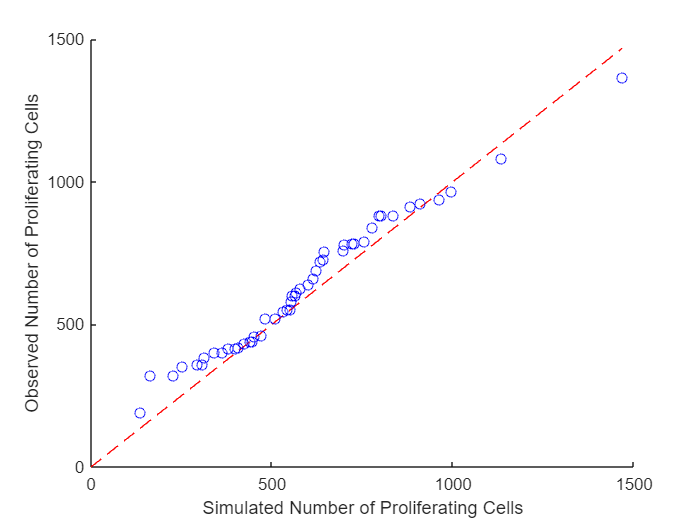

TAS_sim = z(1,:) + z(2,:);
FD_sim = z(3,:);
TOT_sim = TAS_sim + FD_sim;
TAS_sort = sort(TAS_sim);
FD_sort = sort(FD_sim);
TOT_sort = sort(TOT_sim);

figure(1)
clf
hold on
m = max(max(max(TAS_sort(linspace(2,98,49)),TA+18)));
xlabel("Simulated Number of Proliferating Cells")
ylabel("Observed Number of Proliferating Cells")
plot(0:m,0:m,"r--")
scatter(TAS_sort(linspace(2,98,49)),sort(TA + 18),"b")

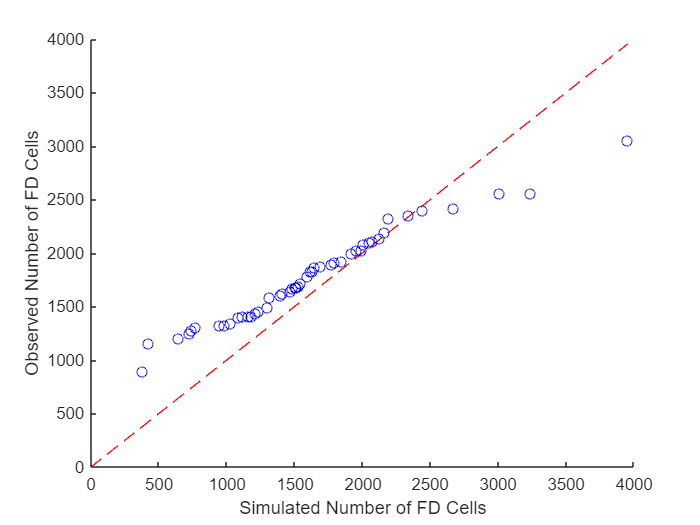


figure(2)
clf
hold on
m = max(max(max(FD_sort(linspace(2,98,49)),FD)));
plot(0:m,0:m,"r--")
xlabel("Simulated Number of FD Cells")
ylabel("Observed Number of FD Cells")
scatter(FD_sort(linspace(2,98,49)),sort(FD),"b")

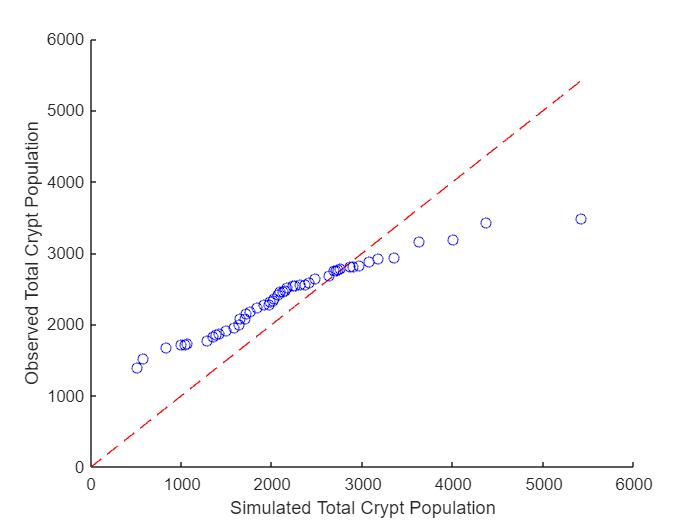


figure(3)
clf
hold on
m = max(max(max(TOT_sort(linspace(2,98,49)),TA+FD+18)));
plot(0:m,0:m,"r--")
xlabel("Simulated Total Crypt Population")
ylabel("Observed Total Crypt Population")
scatter(TOT_sort(linspace(2,98,49)),sort(TA+FD+18),"b")

clear
TA=[880.00
360.00
360.00
760.00
612.00
880.00
936.00
792.00
552.00
400.00
552.00
782.00
690.00
546.00
840.00
520.00
782.00
660.00
432.00
192.00
420.00
400.00
720.00
440.00
912.00
384.00
580.00
456.00
440.00
320.00
414.00
756.00
1364.00
924.00
520.00
1080.00
966.00
600.00
640.00
880.00
600.00
624.00
414.00
728.00
546.00
462.00
320.00
352.00
780.00]-18;

FD=[2552.00
2000.00
1155.00
2400.00
2196.00
1672.00
1872.00
1892.00
1403.00
2075.00
1909.00
1863.00
1495.00
1785.00
2100.00
1716.00
1495.00
2112.00
3051.00
1200.00
1407.00
1320.00
1600.00
1640.00
1680.00
1344.00
2349.00
1691.00
2320.00
2560.00
2139.00
2025.00
1829.00
1617.00
1248.00
1431.00
897.00
1825.00
1280.00
1584.00
1675.00
1920.00
2415.00
2028.00
1449.00
1407.00
1400.00
1320.00
1300.00];

z = manysims(18,618,2373-618,1000,100,"log");
%simulated covariance
CoV = sum((z(2,:)-mean(z(2,:))).*(z(3,:) - mean(z(3,:))))/99;
sim_pearson = CoV/(sqrt(var(z(2,:))*var(z(3,:))))

sim_pearson = 0.9814



%observed covariance
oCoV = sum((TA-mean(TA)).*(FD-mean(FD)))/48;
pearson = oCoV/(sqrt(var(TA)*var(FD)))

pearson = -0.0119